# +microstate example 1: EEG microstate analysis

This example will perform single-subject EEG microstate analysis using the +microstate toolbox. This section will reproduce the analysis described in section 3.1 of the toolbox manuscript [1].

References:

[1] Tait and Zhang (2021) bioRxiv 2021.07.13.452193; doi: [https://doi.org/10.1101/2021.07.13.452193](https://doi.org/10.1101/2021.07.13.452193) 

[2] [https://www.fieldtriptoolbox.org/workshop/madrid2019/tutorial_cleaning](https://www.fieldtriptoolbox.org/workshop/madrid2019/tutorial_cleaning)

If you have any errors or issues with this tutorial, please open an issue via the github issue tracker: [https://github.com/plus-microstate/toolbox/issues](https://github.com/plus-microstate/toolbox/issues) 

To use this Matlab live script, read through each section and try to understand what the code will do. Then press the "Run section" button (in the 'Live Editor' tab at the top of the Matlab control panel) to run each section and see the results inline. 

### Add the data directory to the path

The first thing we need to do is make sure MATLAB can "see" the data. This involves adding the folder which contains the file 'example1_data.mat' to the path. 

toolbox_path = microstate.functions.toolbox_path ; % location where the toolbox is installed
datadir = fullfile(fileparts(toolbox_path),'examples','example1_EEGcanonicalmaps') % path to folder containing the data
addpath(datadir) % add this to the path

If you got an error in this section, you might not have the folder toolbox-master on your Matlab path. Make sure to add this folder to your path, and re-run this section.

### Load the data and format for +microstate

The data used in this tutorial was downloaded and preprocessed as described in the Fieldtrip tutorial for cleaning and preprocessing resting-state EEG data [2]. While you don't need to do any preprocessing or analysis in Fieldtrip for this tutorial (it is already done for you!), the code we used for this preprocessing can be found in toolbox-master/examples/Supplementary_Sripts/fieldtrip_preprocess_data_example1.m if you wish to review it. 

load('example1_data','data') % load the data

If you got an error on the previous line of code, you may not have installed the tutorial data. Try entering `microstate.functions.install('data')` in the command window, and this should download the tutorial data. 

In +microstate, an individual data set should be stored in an *individual *object. To make a microstate *individual *object, we use the code below. We can then import data using the **import_fieldtrip** function. 

ms = microstate.individual ; 
ms = ms.import_fieldtrip(data) 

ms =   individual with properties:

           data: [100000×20 double]
           time: [1×100000 double]
         sample: [1×100000 double]
    bad_samples: [1×0 double]
       modality: 'eeg'
            gfp: [1×100000 double]
           maps: []
          label: [1×0 double]
          stats: [1×1 struct]
        process: [3×2 table]


Alternatively, we can import the data manually. The first input is the time series for the data (each column corresponding to an electrode). The second input specifies this data as EEG data (as opposed to MEG, source, or amplitude envelope data), which is important for the generalized formalism of the microstate algorithm. Finally, the third input gives a time axis or sampling rate (here, we use the time axis). 

timeseries = data.trial{1}' ; % time series in column format
timeaxis = data.time{1} ; % time axis
ms_manualimport = microstate.individual(timeseries,'eeg',timeaxis) 

ms_manualimport =   individual with properties:

           data: [100000×20 double]
           time: [1×100000 double]
         sample: [1×100000 double]
    bad_samples: [1×0 double]
       modality: 'eeg'
            gfp: [1×100000 double]
           maps: []
          label: [1×0 double]
          stats: [1×1 struct]
        process: [2×2 table]


It can be seen in the output that the microstate object `ms` (imported using **import_fieldtrip**) and the microstate object `ms_manualimport` (imported manually) are identical, so you are free to import data however you choose. Other import functions allow for integration with a range of toolboxes, including **import_spm_meeg**,** import_spm_nifti**,** import_brainstorm**,** import_loreta**, and** import_eeglab**. 

### **Perform microstate analysis**

Next, we will pre-process the data and run the microstate analysis. 

For pre-processing, we use the **preprocess** function, which is a wrapper function for **preprocess_filter(1,30) **(bandpass filter 1-30 Hz), **preprocess_rereference** (re-reference to average, EEG only), and **preprocess_resample(min(fsample,256)) **(if sampling rate >256 Hz, resample to 256 Hz. In this case, data is sampled at 250 Hz so no resampling is performed). 

% Preprocess using default settings; re-reference to average, 1-30 Hz
% bandpass filter
ms = ms.preprocess ; 

Subsequently, the function **cluster_estimatemaps** is used to perform microstate analysis. The first input to this function specifies the number of maps. Since we aim to reproduce the four canonical EEG microstate maps, we will cluster 4 maps. When running the code, a red progress bar should update you on the number of replicates completed. 

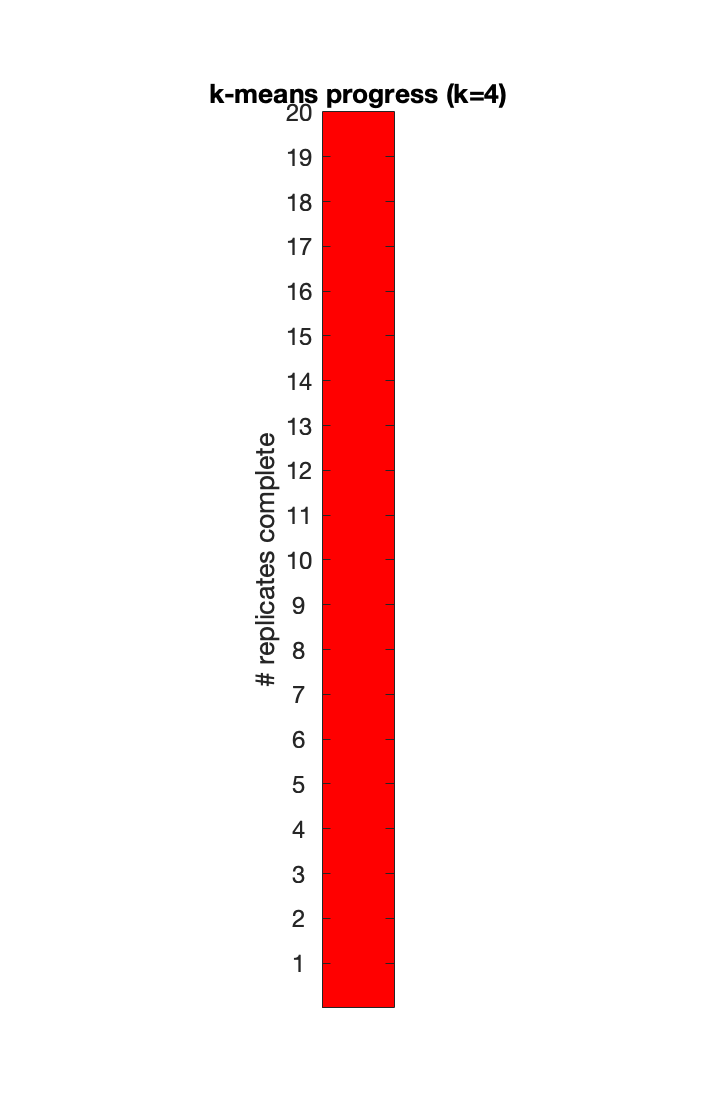

% Perform microstate analysis
rng('default') % for reproducibility
ms = ms.cluster_estimatemaps(4,'plotUpdate',false) ;

### Analyse and visualise the microstate data

To plot the resulting maps, we first need a 2d electrode layout. The simplest way to do this is use the **functions.layout_creator** function. We can call this from the command line by specifying a template system and the labels of the data (in the same order as the data is given in the *individual *object, i.e. `label{i}` should correspond to `ms.data(:,i)`).

% Call layout creator from the command line
template = 'eeg1020' ; % Use the EEG 10-20 system template
labels = {'Fp2';'Fz';'Fp1';'F3';'F7';'C3';'T3';'P3';'T5';'Pz';...
          'O1';'Oz';'O2';'P4';'T6';'C4';'T4';...
          'F8';'F4';'Cz'} ; % equivalent to data.label
layout = microstate.functions.layout_creator(template,labels) ; 

Alternatively, we can manually call the layout_creator GUI by calling the line below. In this case, you will need to save the layout to a file called myLayout.mat, and then load this file. 

% microstate.functions.layout_creator ; % will open GUI
% layout = load('myLayout.mat') ;

Now we can plot the data. The *individual *object has a method associated with it called **plot **for all visualisation, so we can simply call this function specifying we wish to plot the maps. The layout is specified as a 2nd input. 

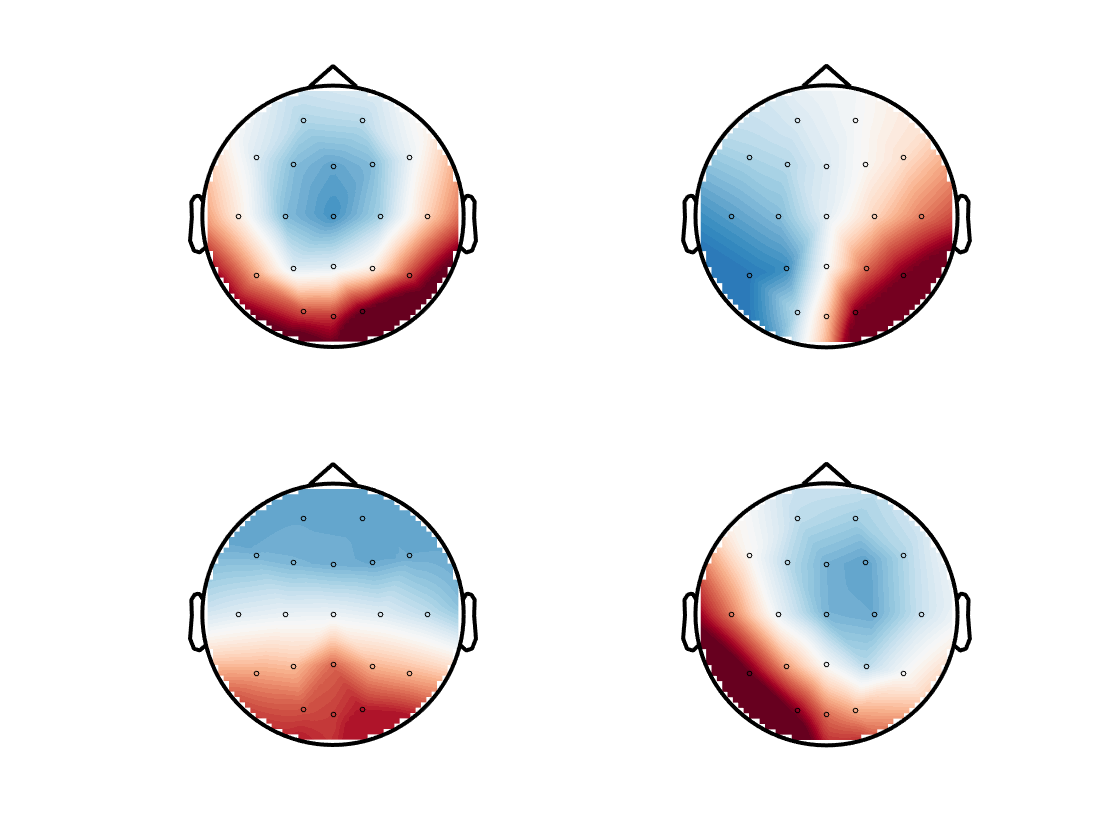

ms.plot('maps',layout);

We can view statistics of the microstate sequences using the **stats_** functions. There are a range of these functions, e.g. to calculate microstate durations you can call **stats_duration**. The **stats_all** function is a wrapped for all stats functions, meaning you can calculate all implemented statistics in one line of code. 

ms = ms.stats_all ; 
stats = ms.stats

stats = struct with fields:
      mean_duration: 0.0544
           duration: [0.0566 0.0517 0.0513 0.0573]
           coverage: [0.2791 0.2064 0.2356 0.2788]
         occurrence: [4.9325 3.9925 4.5975 4.8675]
              hurst: 0.5787
         complexity: [1×1 struct]
    autoinformation: [1×500 double]
             markov: [1×1 struct]
             syntax: [1×1 struct]
      gfp_peaksfreq: 28.1628
                gev: 0.5509
